
a = readstruct('../data/avsleftcam-result/poses.xml');

% Load data
tvec = zeros(numel(a.data), 3);
rvec = zeros(numel(a.data), 3);
rmat = cell(numel(a.data),1);
for i=1:numel(a.data)
    rvec_str = split(a.data(i).rvec, ' ');
    rvec_str = rvec_str(rvec_str ~= "");

    rvec(i,:) = [str2double(rvec_str(1)),...
        str2double(rvec_str(2)),...
        str2double(rvec_str(3))];

    tvec_str = split(a.data(i).tvec, ' ');
    tvec_str = tvec_str(tvec_str ~= "");
    tvec(i,:) = [str2double(tvec_str(1)),...
        str2double(tvec_str(2)),...
        str2double(tvec_str(3))];
end

% Convert from rotation vector to rotation matrix
for i=1:numel(a.data)
    rotmat = rotvec2mat3d(rvec(i,:));
    rmat{i} = rotmat;
    % rmat{i} = inv(rotmat);
end

% Get transformation matrix of camera w.r.t world coordinate
for i=1:numel(a.data)
    A = [rmat{i} tvec(i,:)';
        0 0 0 1];
    invA = inv(A);
    rmat{i} = invA(1:3,1:3);
    tvec(i,:) = invA(1:3,4);
end


eulArray = zeros(numel(a.data), 3);
for i=1:numel(a.data)
    eulArray(i,:) =     rotm2eul(rmat{i});
end

## Draw camera position & orientation

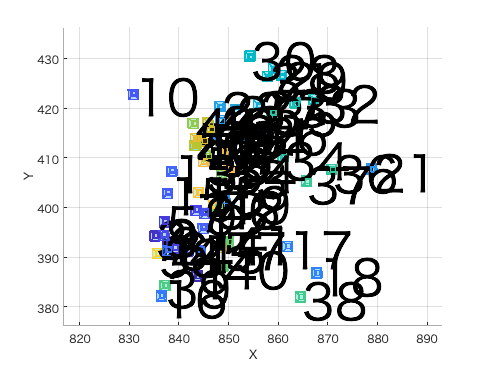

cm = colormap(parula);

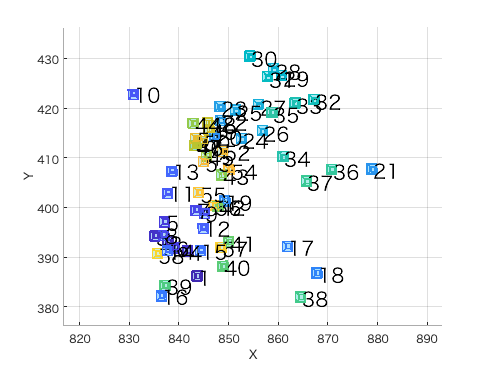


figure;
for i=1:numel(a.data)
text(tvec(i,1), tvec(i,2), tvec(i,3),num2str(i),FontSize=20);
hold on;
cam = plotCamera(AbsolutePose=rigidtform3d(rmat{i}, tvec(i,:)), Size=1, Color=cm(i*4,:));
end
grid on;
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');


% draw board
plot3([0 840 840 0 0], [0 0 1200 1200 0], [0 0 0 0 0], LineWidth=10);
plot3(0,0,0, MarkerSize=10, Color="green", Marker="*"); hold on;

figure;
plot(1:58, -eulArray(:,2));

hold on;
plot(1:58, eulArray(:,3)+pi);
plot(1:58, eulArray(:,3)+pi, '*');

grid on;

plot(1:58, eulArray(:,1)-pi/2, 'LineStyle',':');